# Przetwarzanie sygnałów (preprocessing)

Klaudia Merchut 215IC B1

### Odpowiedzi na pytania

####     W ilu kolumnach zawarty jest dżwięk?

        W 1 jeżeli jest to dźwięk mono, w 2 jeżeli stereo.

####     W jaki sposób można sprawdzić czy czas trwania i całkowity czas trwania dadzą czas trwania jednej próbki? A czy można sprawdzić czy Sample Rate i Total Samples przy odpowiednim obliczeniu "da" Duration?

        Żeby sprawdzić czy *Sample Rate* i *Total Samples* przy odpowiednim obliczeniu "da" *Duration* trzeba całkowity czas próbkowania („Fscalkowite”) pomnożyć przez odwrotność czasu próbkowania (1/Fs) i porównać go ze zmienna „dura”.

### Czyszczenie wszystkiego i przygotowanie programu do pracy

close all; clc; clear; 

### Próbkowanie dźwięku

#### Import dźwięku

Import dźwięku, pobieranie informacji o nim i pobieranie czasu próbkowania.

dzwiek = audioread("01IntroPowiadomienie.mp3");
dzwiekInfo = audioinfo("01IntroPowiadomienie.mp3");
Fs = dzwiekInfo.SampleRate;

#### Utworzenie wykresu 

Przestawienie czasu próbkowania z herzów na sekundy.

czas = 1;
czasFs = czas/Fs;

Ustawienie osi x i y.

[rowDzwiek, colDzwiek] = size(dzwiek);
czasMax = czasFs * rowDzwiek;
czasDzwiek(:,1) = linspace(0, czasMax, rowDzwiek);

Utworzenie wykresu.

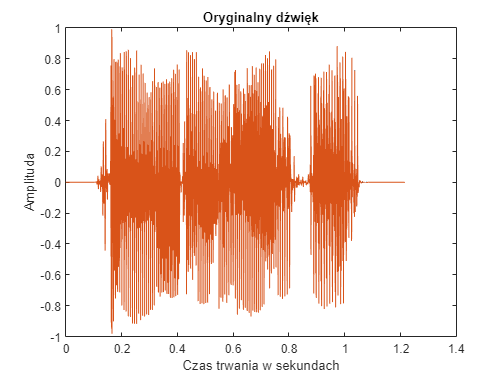

plot(czasDzwiek, dzwiek)

xlim([0.00 1.40])
ylim([-1.00 1.00])
title('Oryginalny dźwięk')
xlabel('Czas trwania w sekundach')
ylabel('Amplituda')

#### Usunięcie ciszy z przodu dźwięku

Szukanie indexów których wartość równa się zero i rozmiar powstałej w skutek poprzedniego działania macierzy.

dzwiek0Idx = find(dzwiek(:,1) == 0);
dzwiek0Size = size(dzwiek0Idx);

Obliczenie różnicy pomiędzy kolejnymi wierszami.

for i =1:dzwiek0Size(1,1)-1
    roznica(i,1) = dzwiek0Idx(i+1,1)-dzwiek0Idx(i,1);
end

Znalezienie ostatniego indexu dla którego wartość macierzy jest równa zero.

roznicaIdxFind = find(roznica>1)

roznicaIdxFind =         4498
        4505
        4508
        4511
        4512
        4513
        4514
        4515
        4516
        4517


roznicaIdx = roznicaIdxFind(1,1)

roznicaIdx = 4498

Utworzenie dźwięku bez ciszy z przodu oraz jego wykresu i nałożenie go na wykres oryginalnego dźwięku .

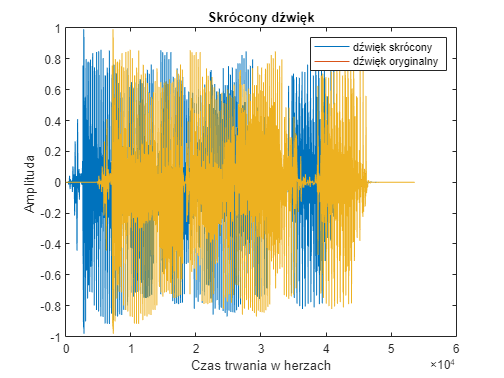

dzwiekBez0(:,1) = dzwiek(roznicaIdx+1:end,1);
plot(dzwiekBez0)
hold on
plot(dzwiek)
hold off

xlim([0 60000])
ylim([-1.00 1.00])
legend({'dźwięk skrócony','dźwięk oryginalny'})
title('Skrócony dźwięk')
xlabel('Czas trwania w herzach')
ylabel('Amplituda ')

#### Usuwanie wartości z przedziału

Ustawienie wartości minimalnej i maksymalnej pożądanej wartości dźwięku.

przedzialMin = -0.1;
przedzialMax = 0.2;

Znalezienie wartości dźwięku w przedziale od min do max, jako iż find zwraca tylko indexy, to jest jeszcze przypisanie wartości do konkretnych indexów.

dzwiekPrzedzialIdx = find(dzwiek(:,1) >= przedzialMin & dzwiek(:,1) <= przedzialMax);
dzwiekPrzedzialVal = dzwiek(dzwiekPrzedzialIdx);

Jako iż dźwięk uległ zmianie to konieczne jest ponowne przeliczenie czasu trwania dźwięku.

[rowPrzedzial, colPrzedzial] = size(dzwiekPrzedzialVal);
czasPrzedzialMax = czasFs * rowPrzedzial;
czasPrz(:,1) = linspace(0, czasPrzedzialMax, rowPrzedzial);
figure(8)

Utworzenie wykresu.

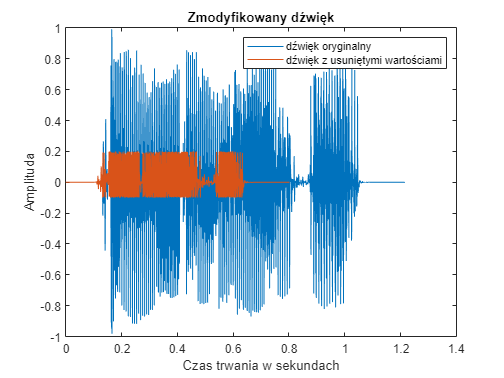

plot(czasDzwiek, dzwiek(:,1), czasPrz,dzwiekPrzedzialVal )

xlim([0.00 1.40])
ylim([-1.00 1.00])
legend({'dźwięk oryginalny','dźwięk z usuniętymi wartościami'})
title('Zmodyfikowany dźwięk')
xlabel('Czas trwania w sekundach')
ylabel('Amplituda')

### Usuwanie wartości nieprawidłowych

#### Import danych

load zestawyLaboratoria.mat

#### Utworzenie wykresu danych na początku

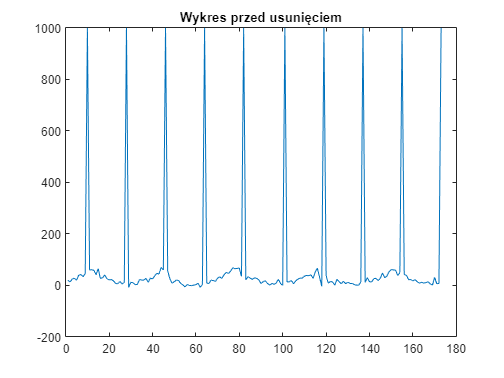

dane=zestaw1{2,1}(:,2);
plot(dane)

title('Wykres przed usunięciem')

#### Usuwanie za pomocą funkcji find, pętli for i instrukcji if

Zapisanie danych z zestawu1, wiersza 2 i kolumny 2 w zmiennej, sprawdzenie 5 wartości maksymalnych dla drugiej kolumny i wielkość macierzy.

danea=zestaw1{2,1}(:,:);
daneaMax=maxk(danea(:,2),5)

daneaMax =         1000
        1000
        1000
        1000
        1000


daneaSize=size(danea)

daneaSize =    173    11


Sprawdzenie czy dany wiersz w drugiej kolumnie ma większą wartość niż wartość przechowywana w daneMax - 300. Jeśli tak to, to w miwjsce tego wiersza wpisuje się wartość z poprzedniego wiersza, jeśli nie, to wiersz zostaje taki jaki jest.

for i=1:daneaSize(1,1)
    if danea(i,2)>(daneaMax(1,1)-300)
        danea(i,2)=danea(i-1,2);
    end
end

#### Za pomocą funkcji ismissing oraz find i pętli for

Zapisanie danych z zestawu1, wiersza 2 i kolumny 2 w zmiennej, sprawdzenie 5 wartości maksymalnych i wielkość macierzy.

Funkcja *ismissing* sprawdza czy w którymś wierszu w zmiennej wystapiły "zakazane" - nieprawidłowe wartości. *Ismissing* przyjmuje wartość 1, jeśli wystąpi nieprawidłowa (podana jako parametr) wartość.

daneb=zestaw1{2,1}(:,2);
danebMax=maxk(daneb, 5)

danebMax =         1000
        1000
        1000
        1000
        1000


danebMissingVal=danebMax(1,1);
danebZestawMissing=ismissing(daneb, danebMissingVal);

Funkcja *find *szuka w których wierszach w 10 kolumnie są 1.

danebFindMissing(:,1) = find(danebZestawMissing(:,1)==1)

danebFindMissing =     10
    28
    46
    64
    82
   101
   119
   137
   155
   173


Sprawdzenie wielkości macierzy z indeksami z nieprawidłowymi wartościami.

sizeFindMis = size(danebFindMissing)

sizeFindMis =     10     1


Żeby nie przeszukiwać całej macierzy wykorzysta się indeksy, gdzie wystąpiły nieprawidłowe wartości.

Bierze kolejne indeksy nieprawidłowych wartości w macierzy i wpisuje się w te miejsca wartości z poprzedniego wiersza. Zmienna pomocnicza zapisuje wartości poprawne o wiersz niżej niż błędna wartość.

for i=1:sizeFindMis(1,1)
    pom=danebFindMissing(i,1)-1
    dane(danebFindMissing(i,1),2)=daneb(pom,1);
end

pom = 9

pom = 27

pom = 45

pom = 63

pom = 81

pom = 100

pom = 118

pom = 136

pom = 154

pom = 172

#### Utworzenie wykresu danych na końcu

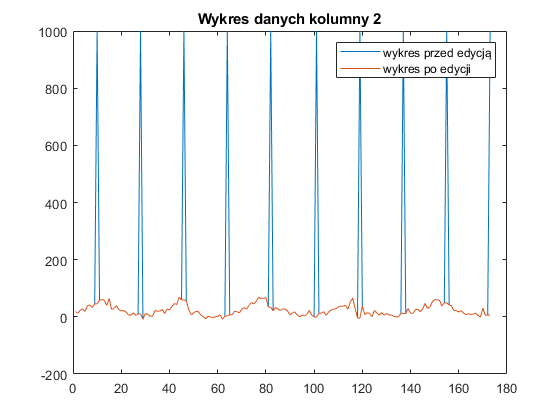

plot(daneb)
hold on
plot(danea(:,2))
hold off

legend({'wykres przed edycją','wykres po edycji'})
title('Wykres danych kolumny 2')

### Porównanie sygnałów

%open my_figure.m
load 2022_garmin_data.mat

t = zestaw1{2,1}(:,1);
moc = zestaw1{2,1}(:,10);
sila = danea(:,2);
[N, nn] = size(sila);
N = size(sila);
N=N(1,1)

N = 173

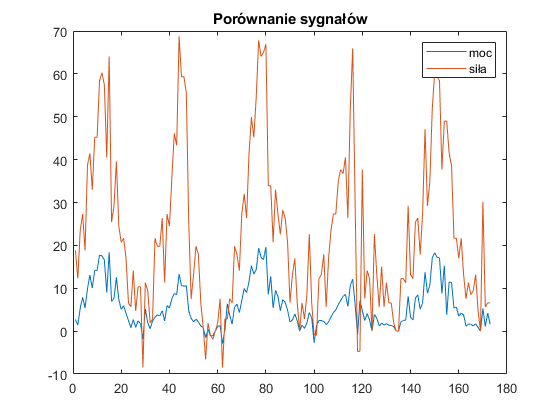

plot(moc)
hold on
plot (sila)
hold off

legend({'moc','siła'})
title('Porównanie sygnałów')

#### Współczynnik kowariancji

m_cov = cov(sila,moc)

m_cov =   353.7018   89.2069
   89.2069   26.2119


#### Funkcja kowariancji

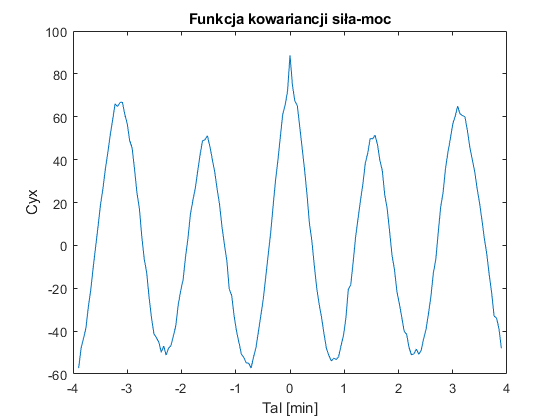

[f_cov, lags] = xcov(sila, moc, 'unbiased',round(N/2));
tal=lags*dt;
figure; 
plot(tal, f_cov); 
title('Funkcja kowariancji siła-moc')
xlabel('Tal [min]')
ylabel('Cyx')

#### Współczynnik korelacji

m_kor = corrcoef(sila, moc)

m_kor =     1.0000    0.9265
    0.9265    1.0000


#### Funkcja korelacji

[f_kor_raw, lags] = xcorr(sila, moc, 'unbiased', round(N/2));
figure; subplot(211);
plot(tal, f_kor_raw);
title('Funkcja korelacji siła-moc')
xlabel('Tal [min]')
ylabel('Rxy raw')

#### Unormowana funkcja korelacji

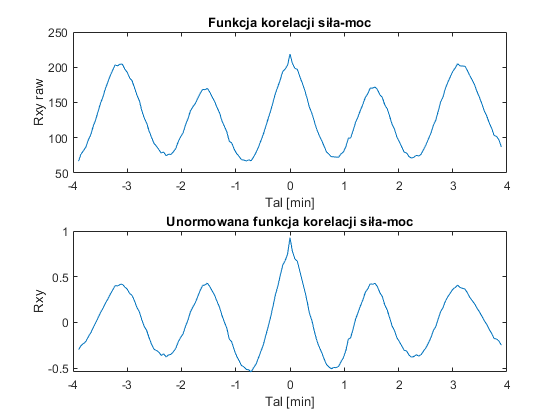

[f_kor_norm, lags] = xcorr(sila - mean(sila), moc - mean(moc), 'coef',round(N/2));
tal=lags*dt;
subplot(212)
plot(tal, f_kor_norm);
title('Unormowana funkcja korelacji siła-moc')
xlabel('Tal [min]')
ylabel('Rxy')